**ФЕДЕРАЛЬНОЕ АГЕНТСТВО ЖЕЛЕЗНОДОРОЖНОГО ТРАНСПОРТА **

Федеральное государственное бюджетное образовательное учреждение высшего образования

**«Петербургский государственный университет путей сообщения **

**Императора Александра ****I****»**

**(ФГБОУ ВО ПГУПС)**

Факультет «Транспортные и энергетические системы»

Кафедра «Электрическая тяга»

Специальность 25.05.03 «Подвижной состав железных дорог»

Специализация «Электрический транспорт»

Дисциплина «Компьютерное моделирование электрооборудования ЭПС»

**Отчет по ТЗ №3**

**«Разработка математической модели разомкнутой системы управления электроприводом»**

**Вариант №5**

 **Выполнил студент**

 **Курс: 5**

**Группа: ПС-003**

Дулепов И.Г.

                                                                                     ______________      

                                                                                      (Дата, подпись)   

  **Руководитель                                                                                                                                                                           **Сычугов А.Н.                                                                                                                                   

                                                                                    ______________      

                                                                                      (Дата, подпись)                                                        

Санкт-Петербург 

2024

**Типовая задача №3. Компьютерная модель системы тягового энергоснабжения и тягового электропривода с КТД:**

## **Введение:**

**Цель работы - **Разработка математической модели разомкнутой системы управления электроприводом. Получение диаграмм напряжения на нагрузке, токов ТЭД, скорости,  силы тяги, а также токов и напряжений на фильтре (в случае λ=0,5 , ОП=100%).

На рисунке 1 представлена схема импульсного регулирования напряжения двигателя постоянного тока независимого возбуждения в соответствии с вариантом типового задания.

 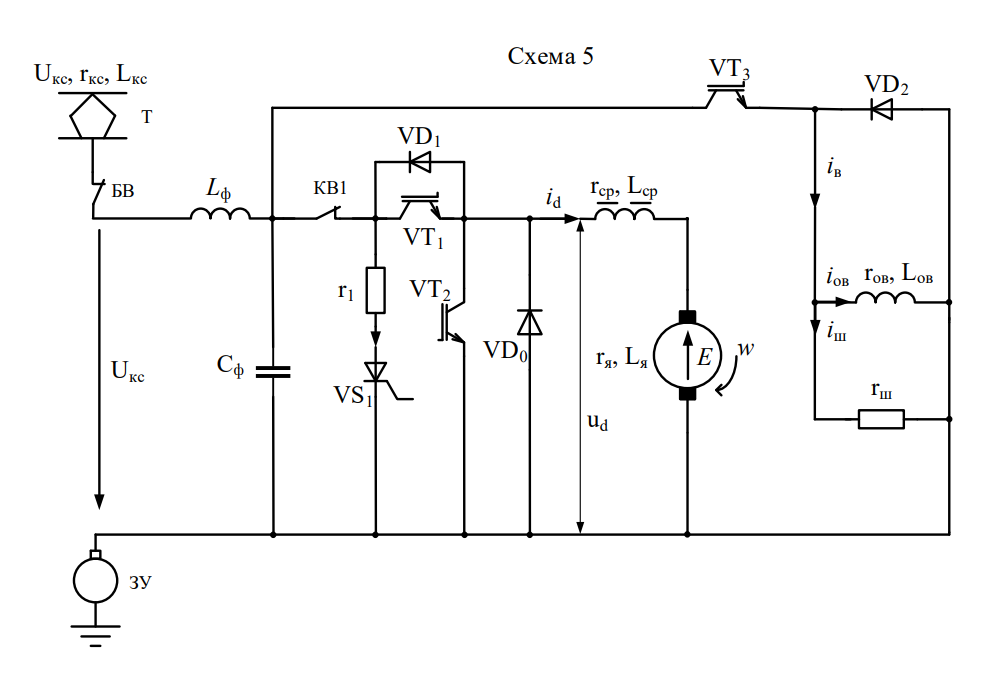

Рисунок 1. Схема импульсного регулирования напряжения при независимом возбуждении ТЭД.

## **1. Схема модели системы тягового энергоснабжения и тягового электропривода с КТД в Simulink:**

Компьютерная модель силовой цепи и САУ ТЭД ЭПС постоянного тока с широтно-импульсным регулированием напряжения предназначена для моделирования и исследования переходных процессов, связанных с изменением токов и напряжения тяговых электродвигателей при пуске, движении по участку и электрическом торможении.

Компьютерная модель воспроизводит силовую цепь одной секции ЭПС. 

Компьютерная модель системы тягового энергоснабжения и тягового электропривода с КТД в Simulink привидена на рисунке 2.

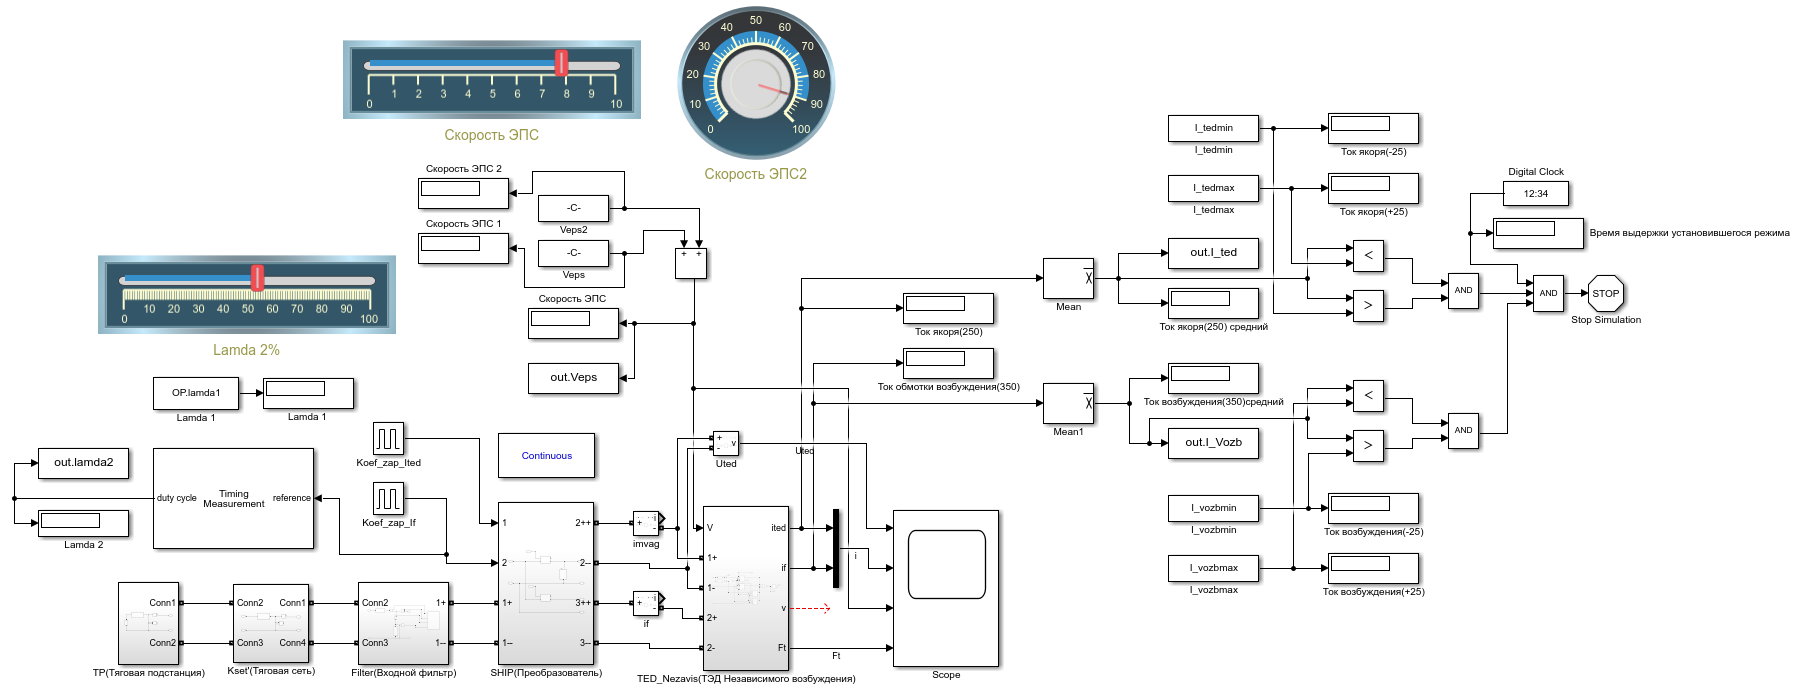

Рисунок 2. Компьютерная модель системы тягового энергоснабжения и тягового электропривода с КТД в Simulink

## **2. Задание исходных данных в модель:**

### **2.1. Задание параметров тяговой подстанции:**

Компьютерная модель тяговой подстанции в Simulink приведена на рисунке 3.

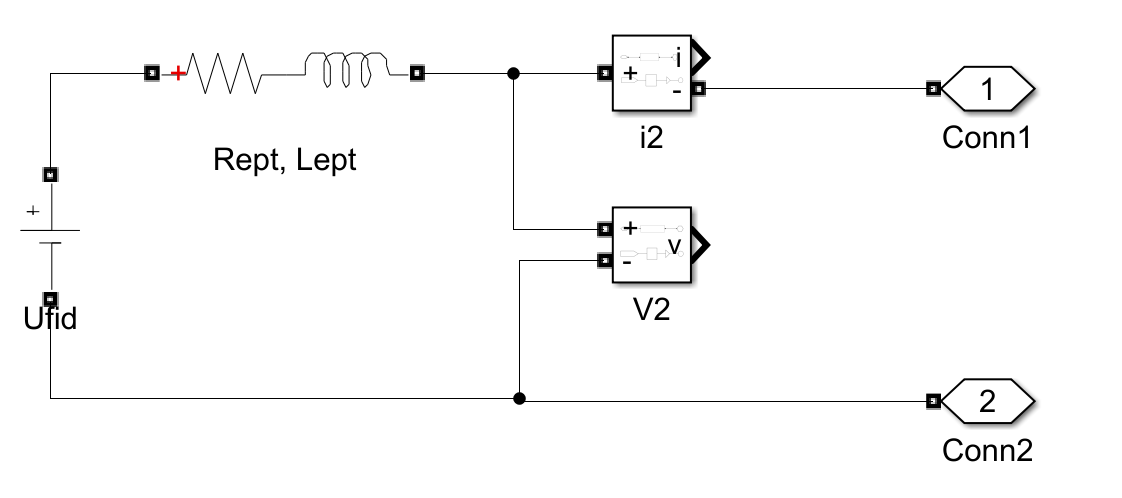

Рисунок 3. Компьютерная модель тяговой подстанции в Simulink

Тяговую подстанцию постоянного тока можно представить схемой замещения, состоящей из источника питания со средневыпрямленным напряжением Ud0 (Uтп=Ud0), индуктивности и сопротивления тяговой подстанции Lтп и Rтп.

Компьютерная модель тяговой подстанции составлена из блоков источника питания «Ufid» (Ufid=Ud0), индуктивности и сопротивления  тяговой подстанции «Retp» и «Letp». При вводе параметров сопротивлений и индуктивностей тяговой под станции необходимо учитывать количество тяговых секций ЭПС Nтc.

**Напряжение тяговой подстанции Uтп, В.:**

TP.U_tp = 3450;

**Активное сопротивление тяговой подстанции «Retp», Ом:**

При:

- суммарном активном сопротивлении тяговой подстанции приведенном к тяговой обмотке трансформатора Rтп, Ом. (см. ТЗ2):

R_tp = 0.0205; %Величина из расчета Rтп в ТЗ2

- количестве тяговых секций ЭПС:

N_ts = 3; %Согласно исходным данным и ТЗ2

Тогда:

TP.R_etp = N_ts*R_tp;

**Индуктивность тяговой подстанции «Letp», Гн:**

При:

- частоте работы тяговой подстанции, Гц:

TP.f_c = 50;

- индуктивности тяговой подстанции приведенной к тяговой обмотке трансформатора Lтп, Гн.

L_tp = (R_tp/TP.f_c)*2;

Тогда:

TP.L_etp = N_ts*L_tp;

### **2.2. Задание параметров тяговой сети:**

Компьютерная модель тяговой сети в Simulink приведена на рисунке 4.

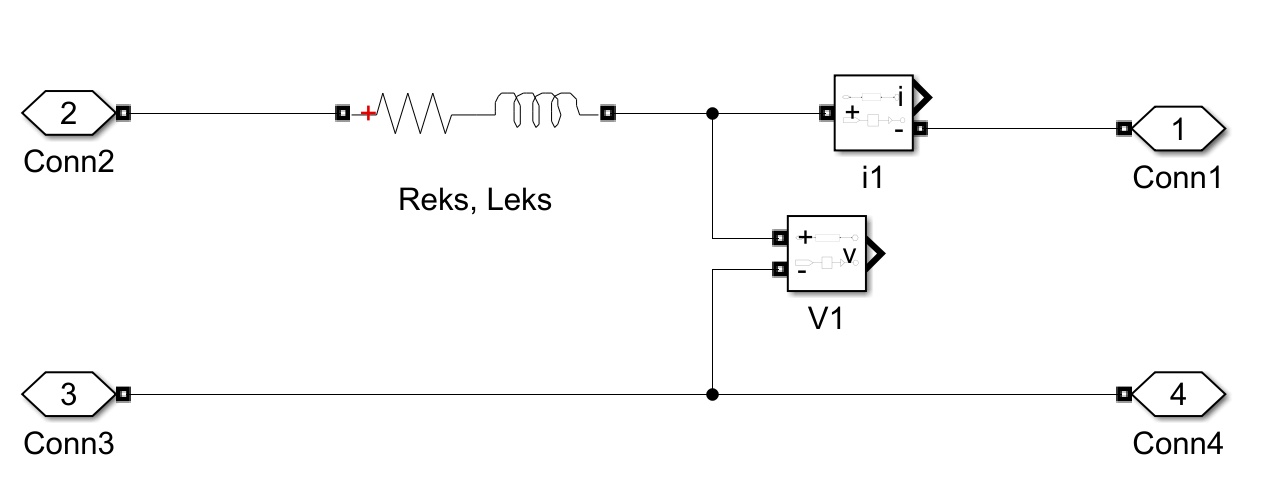

Рисунок 4. Компьютерная модель тяговой сети в Simulink

Модель тяговой сети представляет собой блок последовательно соединенных элементов: сопротивления Rekc и индуктивности Lekc.

**Активное сопротивление тяговой сети «Rekc», Ом:**

при 

 - активном сопротивлении ТС (тяговой сети) Rтс, Ом. (см. ТЗ2):

R_ts = 0.2295; %Величина из расчета Rтс в ТЗ2

Тогда:

TS.R_eks = N_ts*R_ts;

**Индуктивность тяговой сети  «Lekc», Гн:**

где Lтс - Индуктивность ТС (тяговой сети), которая определяется по следующей формуле:

где 𝐿′тс [Гн/км] внутренняя и внешняя 𝐿′′тс [Гн/км] индуктивности тяговой сети.

В расчетах примем (𝐿′тс + 𝐿′′тс) = (3,05÷5,34)*10-3 Гн/км 

      l = lтп –  протяженность контактной и рельсовой цепей (расстояние от ЭПС до тяговой подстанции), км (см. ТЗ2):

l = 9; %км. Согласно исходным данным и ТЗ2

Тогда:

L_ts = (3.05*(10^-3))*l;

Отсюда:

TS.L_eks = N_ts*L_ts;

### **2.3. Задание параметров входного Г-образного фильтра:**

Компьютерная модель входного фильтра в Simulink приведена на рисунке 5.

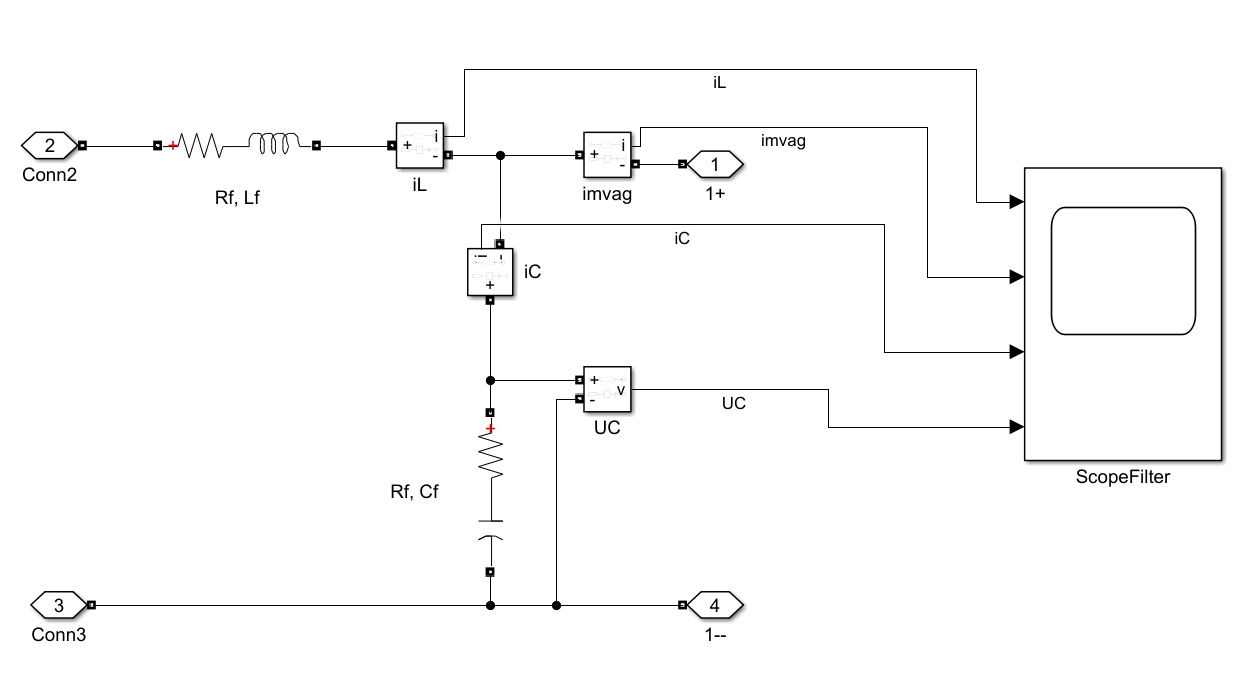

Рисунок 5. Компьютерная модель входного фильтра в Simulink

**Активное сопротивление входного фильтра «Rf», Ом:**

Активное сопротивление входного фильтра примем равным Rf = 0.001 Ом.

Filter.R_f = 0.001;

**Индуктивность и емкость входного фильтра «Lf», Гн. и «Cf», Ф. соответственно:**

Выражение для определения емкости конденсатора фильтра может быть получено из равенства:

Для расчета емкости задаемся допустимой величиной пульсации напряжения на фильтровом конденсаторе, величиной тока секции ЭПС, индуктивностью фильтра, относительным периодом коммутации $\beta$ и частотой работы преобразователя fпр. Величину пульсации напряжения на фильтровом конденсаторе ΔUCmax принимаем равным 50 В, $\beta$=0,1÷0,2.

Система уравнений для определения емкости конденсатора и индуктивности фильтра:

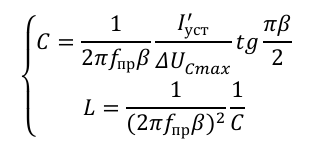

В случае питания параллельных ветвей с последовательным соединением ТЭД от одного преобразователя и фильтра ток уставки принимаем равным, А.:

где a тэд – число параллельных ветвей ТЭД, питающихся от одного преобразователя и фильтра.

При:

a_ted = 2;
I_ust = 250;
I_ust1 = I_ust*a_ted;

Отсюда:

**Емкость входного фильтра «Cf», Ф.:**

при:

- величине пульсации напряжения на фильтровом конденсаторе ΔUCmax, В.:

Filter.deltaUC_max = 50;

- относительном периоде коммутации $\beta$:

Filter.beta = 0.15;

- частоте работы преобразователя f, Гц:

source.f_c = 700; %Согласно исходным данным и ТЗ2

Тогда:

Filter.C_f = (1/(2*pi*source.f_c*Filter.beta))*(I_ust1/(Filter.deltaUC_max))*tan((pi*Filter.beta)/2);

**Индуктивность входного фильтра «Lf», Гн.:**

Filter.L_f = (1/((2*pi*source.f_c*Filter.beta)^2))*(1/Filter.C_f);

### **2.4. Модель тягового привода:**

Компьютерная модель тягового привода в Simulink (рисунок 6) содержит четыре тяговых двигателя, два сглаживающих реактора и механическую часть, которая воспроизводится уравнениями движения поезда.

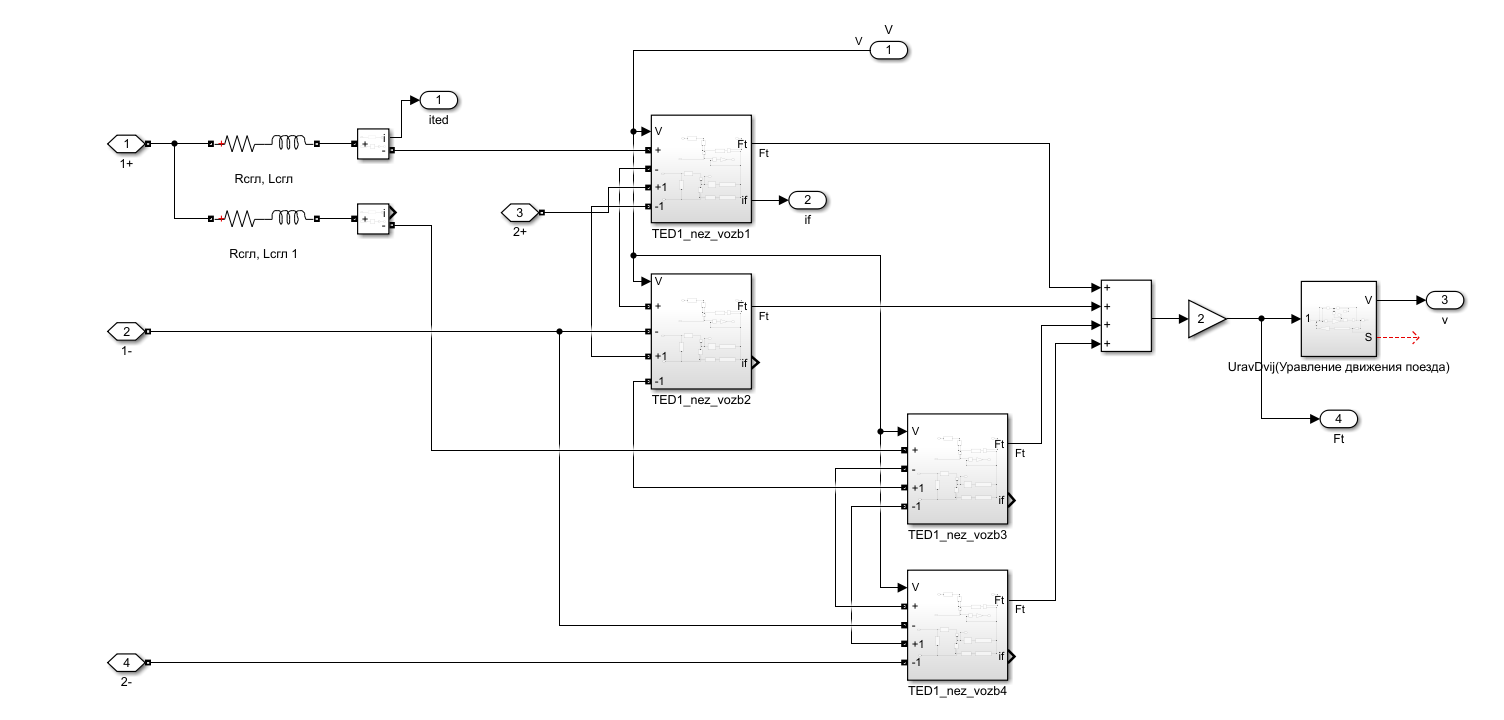

Рисунок 6. Компьютерная модель тягового привода в Simulink

**Активное сопротивление сглаживающих реакторов «Rсгл», Ом:**

Активное сопротивление сглаживающего реактора примем равным Rсгл = 0.001 Ом.

TagPr.R_sgl = 0.001;

**Индуктивнось сглаживающих реакторов «Lсгл», Гн:**

 Индуктивность сглаживающего реактора Lсгл в цепи ТЭД можно рассчитать по формуле, Гн:

где    KI - коэффициент пульсации, характеризующий отклонение тока от среднего значения. Допустимые значения коэффициента необходимо принимаем в диапазоне от  0,01 до 0,1.

Тогда индуктивность сглаживающего реактора Lсгл, Гн:

RaLa.Res = 0.05; %Сопротивление якоря, доп. полюсов, компенсационной обмотки, Ом
TagPr.K_I = 0.1;
U_ks = 3.0749*10^3; %В.
RaLa.Ind = 0.0032; %Гн.
TagPr.L_sgl = (1/source.f_c)*(0.5*RaLa.Res+0.25*(U_ks/(TagPr.K_I*I_ust)))-RaLa.Ind; %Гн.
%0.0207;

**Параметры в блоках тяговых двигателей задаем согласно расчетов в типовом задании 1 (ТЗ1) и исходным данным:**

Параметры сопротивления и индуктивности обмотки якоря, Ом, Гн:

RaLa.Res =0.05;
RaLa.Ind = 0.0032;

Параметры сопротивления и индуктивности обмотки возбуждения, Ом, Гн:

ReLe.Res = 0.1;
ReLe.Ind = 0.0076;

Параметры характеристики намагничивания ТЭД:

CF.currentvozb = [0 25 50 100 150 175 200 250 300 350 400 450];
CF.CvF = [0 5 7.7 12.1 14.3 15 15.5 16.5 17.1 17.6 17.9 18.2];

Сопротивление шунтирующего резистора постоянного шунтирования ТЭД с коэффициентом β0=0,98 Ом.:

Rsh0.Res = 4.9;

Постоянная времени контура вихревых токов ТЭД Tвх, с:

Tokivx.time = 0.0230;

Коэффициент усиления дифференцирующего звена определяется числом витков полюсных катушек ТЭД, с(км/ч): 

Es.coefficient = 1.8471;

### **2.5 Уравнение движения поезда:**

Уравнение равновесия механических сил, действующих на ЭПС,  воспроизводит модуль «UrDvij». Модуль «UrDvij» воспроизводит действие сил инерции и сил сопро тивления движению поезда. Компьютерная модель функциональной схемы модуля в Simulink, в случае моделирования мотор-вагонного подвижного состава, показана на рисунке 7.

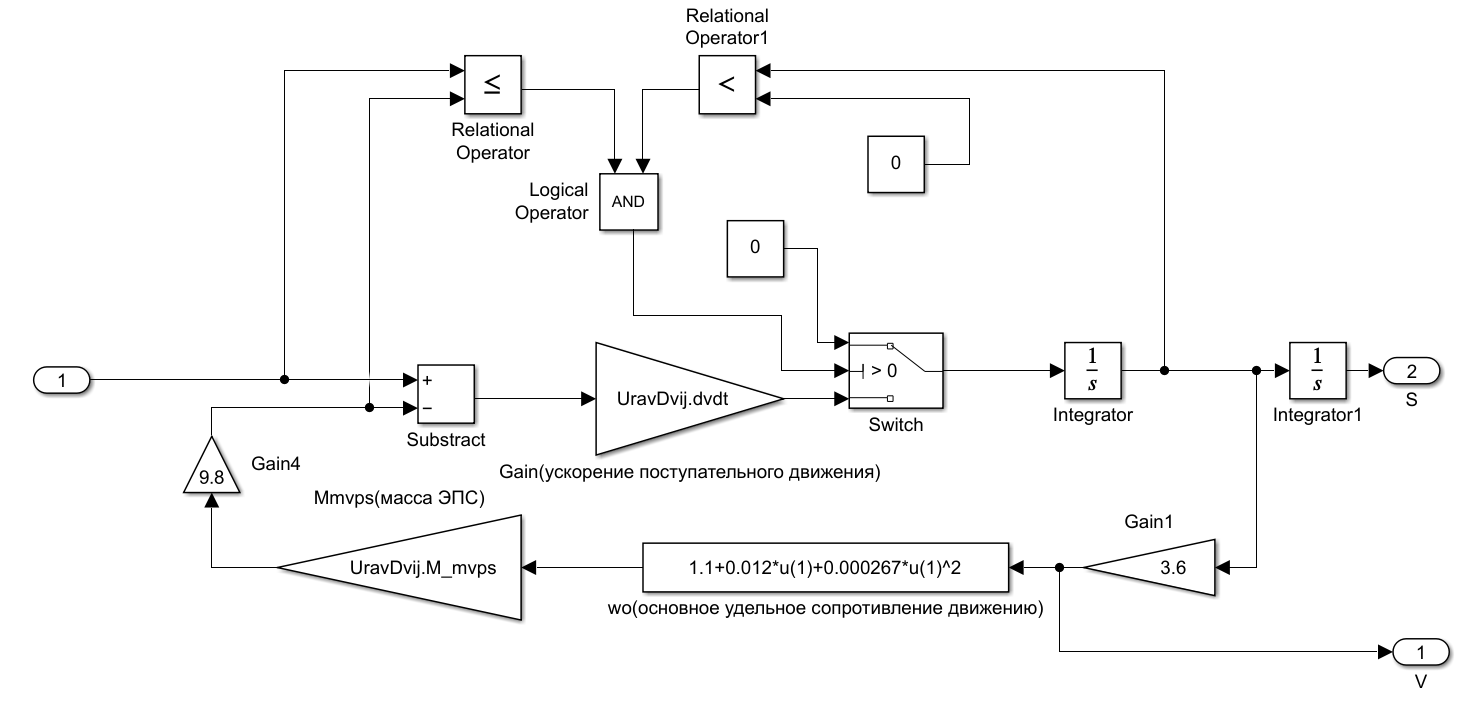

Рисунок 7.  Компьютерная модель уравнений движения ЭПС 

Модуль «Gain1» переводит единицы измерения м/с в км/ч. 

Модули «wo», «Mmvps» и «Gain4» формируют силы сопротивления движению ЭПС:

где Mэпс - масса ЭПС, т;

v – скорость движения электровоза (электропоезда), км/ч;

a, b, c- эмпирические коэффициенты расчета сил сопротивления движению состава

Поскольку для заданного варианта курсового проекта выбран тип тяговых электродвигателей ТЭД-3У, устанавливающихся в настоящее время на моторвагонный подвижной состав переменного тока (ЭД9М), то эмпирическая формула основного удельного сопротивления движению ЭПС при движении под током будет описыватся следующим уравнением, Н/кН:

где V - скорость поезда, км/ч.

%UravDvij.wo = 1.1+0.012*u(1)+0.000267*u(1)^2 %в блоке задания данного
%уравнения для корректной работы системы формулу пишем полностью

Массу ЭПС в случае МВПС рассчитываем по следующей формуле:

где   Мм, Мг, Mпр, - масса моторного, головного и прицепного вагона соответственно;

Из справочных материалов методических указаний (табл. 12) "Масса различного типа ЭПС и вагонов":

- масса моторного, головного и прицепного вагона МВПС, т.:

UravDvij.M_m = 61;
UravDvij.M_pr = 45;
UravDvij.M_g = 41;

        Nм, Nг, Nпр – число моторных, головных и прицепных вагонов в поезде соответственно;

UravDvij.N_m = 3;
UravDvij.N_pr = 3;
UravDvij.N_g = 2;

        αзаг – коэффициент загрузки вагонов.

UravDvij.a_zag = 0.8; %80 процентов загрузки (согл. исходным данным)

        Мпас – масса пассажиров в одном вагоне поезда, кг.: 

Из справочных материалов методических указаний (табл. 13) "Населенность вагонов", мест:

UravDvij.N_mest = 110;

Отсюда Мпас, т.:

UravDvij.M_pas=(70*UravDvij.N_mest)*10^-3;

Отсюда масса МВПС, т.:

UravDvij.M_mvps = (UravDvij.M_m*UravDvij.N_m+UravDvij.M_g*UravDvij.N_g+UravDvij.M_pr*UravDvij.N_pr)+UravDvij.M_pas*(UravDvij.N_m+UravDvij.N_g+UravDvij.N_pr)*UravDvij.a_zag;

UravDvij = struct with fields:
       M_m: 61
      M_pr: 45
       M_g: 41
       N_m: 3
      N_pr: 3
       N_g: 2
     a_zag: 0.8000
    N_mest: 110
     M_pas: 7.7000
    M_mvps: 449.2800


Модуль «Substract» осуществляет суммирование силы тяги ЭПС и сил сопротивления Wo.

Модуль «Gain» формирует производную скорости движения (ускорения поступательного движения)  dv/dt  , м/с2, выполняя деление выходного сигнала суммарных сил блока «Substract» на массу ЭПС Mэпс, т с учетом инерции вращающихся элементов экипажной части состава:

где (1+γ) - коэффициентов инерции вращающихся частей (Из справочных материалов методических указаний (табл. 14)):

- для электропоездов и электровозов:

UravDvij.gamma = 0.07;

Тогда ускорение поступательного движения, м/с2:

UravDvij.dvdt = 1/1000/UravDvij.M_mvps/(1+UravDvij.gamma);

### **2.6. Задание параметров широтно-импульсного преобразователя:**

**Параметры в блоках широтно-импульсного преобразователя задаем согласно расчетов в типовом задании 2 (ТЗ2) и исходным данным:**

Частота работы преобразователя, Гц:

source.f_c = 700;

Параметры IGBT транзистора:

Resistance Ron (Ohms):

IGBT.R_on = 0.0020; %Ом.

Forward voltage Vf (V) (Vce(on)):

deltaV_ce = 1; %В.
IGBT.V_f = deltaV_ce; %В.

Параметры силового диода (Diode):

Активное сопротивление силового диода rт, Ом:

Diode.r_t = 1.2*(10^-3);

Snubber resistance Rs (Ohms):

Diode.R_s = 5*10^6;

## **3. Порядок выполнения исследований:**

**Независимое возбуждение:**

Меняем: v-скорость электропоезда, λ1-коэффициент заполнения (задается по таблице 2 типового задания №3), который задает величину напряжения на обмотках якорей ТЭД, λ2 - коэффициент заполнения, который задает величину напряжения на обмотках возбуждения ТЭД.

Выставляем требуемую величину коэффициента заполнения λ1 (задается в коде программы (пункт 3)), варьируя скорость движения ЭПС и коэффициент заполнения λ2 с помощью ползунков в симулинк (после запуска программы кнопкой "Run" открывается компьютерная модель схемы в Simulink (рисунок 2)) добиваемся того, чтобы ток якорей был равен заданному току Iуст , а ток возбуждения равен току Iян. Значения получаемых токов выводятся на схеме с помощью дисплеев "Ток якоря", "Ток возбужденя". По выставленной погрешности измерения токов при попадании в диапазон измерения снимаемых величин, программа автоматически запишет результат и перейдет к следующему шагу расчета. Погрешноть измерения токов задаются в пунктах 2 и 4 расчета.

Далее переходим к следующим измерениям токов при следующей заданной величине коэффициента заполения λ1, пока не он станет равным максимальной величине λ1=0,99, тогда начинаем снижать уже ток возбуждения при помощи коэффицинта заполнения λ2 до величины 0.75 Iян. Далее варьируя скорость и λ2 добиваемся того, что ток якорей был равен заданному, а ток возбуждения 0.75 Iян, после переходим к следующему опыту – ток возбуждения Iв ном=0.5 Iян.

1) Подготавливаем массивы для снятия параметров измерений:

N_op = [];
lamda1 = [];
lamda2 = [];
V_eps = [];
I_ya = [];
I_Vozb = [];

2) Задаем параметры диапазона измерений тока якоря и тока возбуждения Iуст и Iян соответственно:

- диапазон для тока якоря:

I_ted = I_ust;
I_tedmin = I_ted-2.5;
I_tedmax = I_ted+2.5;

- диапазон для тока возбуждения:

Imax.current = 350;
I_vozb = Imax.current;
I_vozbmin = I_vozb-2.5;
I_vozbmax = I_vozb+2.5;

3) Задаем параметры коэффициента заполнения λ1:

Коэффициент заполнения λ1 в первых двух опытах меняем в диапазоне от 0,1 до 0,5. В последних трех опытах λ1 = 0,99.

lam1 = [0.1 0.5 0.99].'; %диапазон задаваемых значений λ1 в первых трех опытах

4) Перемещая ползунки коэффициента заполнения λ2 и скорости ЭПС v добиваемся того, чтобы ток якорей был равен заданному Iуст = 250+-25 А., а ток возбуждения равен Iян = 350+-25 А.

Производим снятие параметров в первых трех опытах:

Открываем и запускаем модель в Simulink:

open ('SustemTagSnab_and_TagElPrivod.slx');
for l1 = lam1(1:1:end).'
    OP.lamda1 = l1;
    sim ('SustemTagSnab_and_TagElPrivod.slx');
    lamda1(end+1) = OP.lamda1(end, 1);
    V_eps(end+1) = max(ans.Veps(end, 1));
    I_ya(end+1)  = max(ans.I_ted(end, 1));
    lamda2(end+1) = max(ans.lamda2(end, 1));
    I_Vozb(end+1) = max(ans.I_Vozb(end, 1));
end

Производим снятие параметров в четвертом опыте:

В опыте №4 при коэффициенте заполнения λ1 = 0,99 добиваемся того, чтобы ток возбуждения был равен току Iян = 0,75*350 А.

lam1 = 0.99; %значение λ1 в четвертом опыте

- диапазон для тока возбуждения в четвертом опыте:

Imax.current = 350*0.75;
I_vozb = Imax.current;
I_vozbmin = I_vozb-2.5;
I_vozbmax = I_vozb+2.5;

Открываем и запускаем модель в Simulink:

%open ('SustemTagSnab_and_TagElPrivod.slx');
for l1 = lam1(1:1:end).'
    OP.lamda1 = l1;
    sim ('SustemTagSnab_and_TagElPrivod.slx');
    lamda1(end+1) = OP.lamda1(end, 1);
    V_eps(end+1) = max(ans.Veps(end, 1));
    I_ya(end+1)  = max(ans.I_ted(end, 1));
    lamda2(end+1) = max(ans.lamda2(end, 1));
    I_Vozb(end+1) = max(ans.I_Vozb(end, 1));
end

Производим снятие параметров в пятом опыте:

В опыте №5 при коэффициенте заполнения λ1 = 0,99 добиваемся того, чтобы ток возбуждения был равен току Iян = 0,5*350 А.

lam1 = 0.99; %значение λ1 в четвертом опыте

- диапазон для тока возбуждения в пятом опыте:

Imax.current = 350*0.5;
I_vozb = Imax.current;
I_vozbmin = I_vozb-5;
I_vozbmax = I_vozb+5;

Открываем и запускаем модель в Simulink:

%open ('SustemTagSnab_and_TagElPrivod.slx');
for l1 = lam1(1:1:end).'
    OP.lamda1 = l1;
    sim ('SustemTagSnab_and_TagElPrivod.slx');
    lamda1(end+1) = OP.lamda1(end, 1);
    V_eps(end+1) = max(ans.Veps(end, 1));
    I_ya(end+1)  = max(ans.I_ted(end, 1));
    lamda2(end+1) = max(ans.lamda2(end, 1));
    I_Vozb(end+1) = max(ans.I_Vozb(end, 1));
end

5) Параметры проводимых исследований  и полученные величины λ2 и v заносим в таблицу 1.

Nop = height(lamda1.'); %количество произвдененных опытов
N_op = (1:1:Nop);
T_OPtz3 = table(N_op.',lamda1.',I_ya.',I_Vozb.',lamda2.',V_eps.');
T_OPtz3.Properties.VariableNames = ["№ Опыта","λ1", "Iуст, А.","Iв, А.", "λ2", "V, км/ч."];
disp(T_OPtz3);

    № Опыта     λ1     Iуст, А.    Iв, А.      λ2       V, км/ч.
    _______    ____    ________    ______    _______    ________

       1        0.1     252.34     351.83    0.69977     8.2261 
       2        0.5      247.5      347.8    0.70775         42 
       3       0.99     250.96      351.6    0.72384     78.321 
       4       0.99      247.5     260.42    0.64204     85.168 
       5       0.99     250.79     177.03    0.54846     96.377 



## **4. Диаграммы токов и напряжений, кривые движения поезда:**

Останавливаем расчет и снимаем показания по осциллографа на интервалах соответствующих опытам 1-5 исследований таблицы 1.

Масштаб построения осцилограмм по горизонали:

x.min = 9.99;
x.max = 9.996;

### **4.1. Диаграммы осциллографа при λ1=0.1, λ2=0.7, β=1, v=8,23 км/ч  Iуст=250А, Iв=350А:**

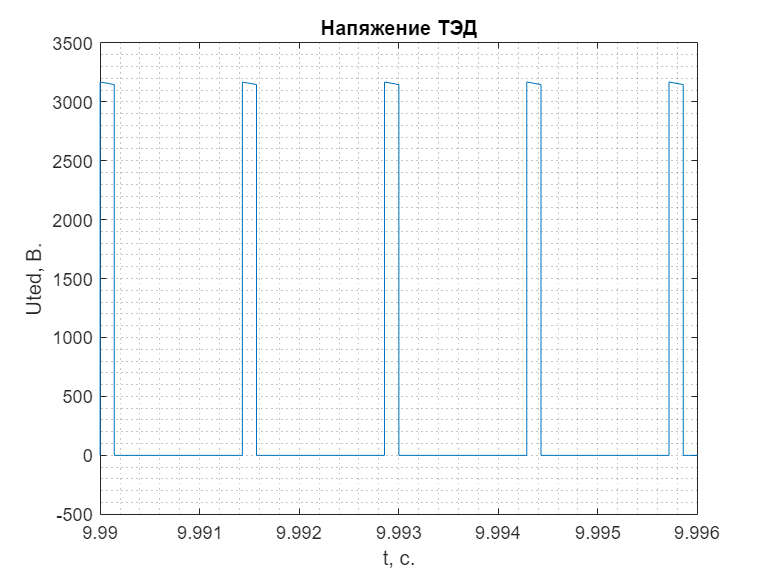

open ('SustemTagSnab_and_TagElPrivod_Scope.slx');
for l1 = 0.1
    OP.lamda1 = l1;
    OP.Veps = V_eps(1:1).';
    OP.lamda2 = lamda2(1:1).';
    sim ('SustemTagSnab_and_TagElPrivod_Scope.slx');
end  
    plot(ans.ScopeTED{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Uted, В.');
    title('Напяжение ТЭД');
    xlim([x.min x.max]);

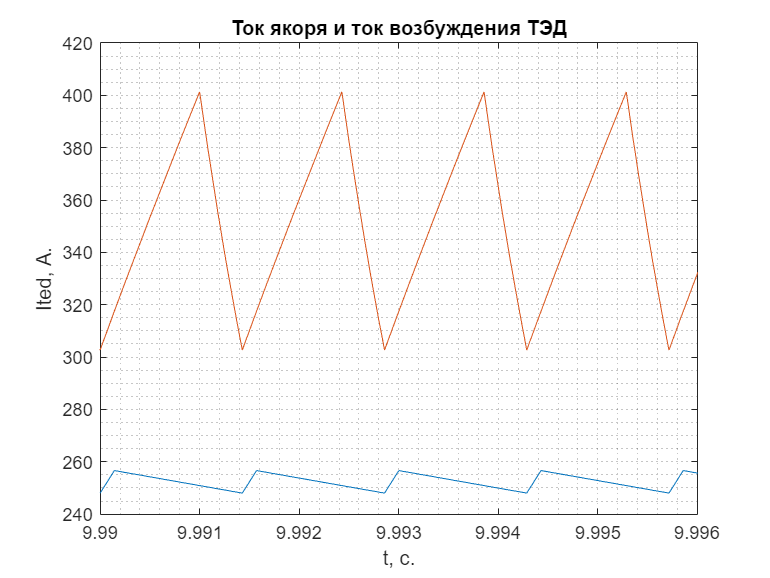

    plot(ans.ScopeTED{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ited, А.');
    title('Ток якоря и ток возбуждения ТЭД');
    xlim([x.min x.max]);

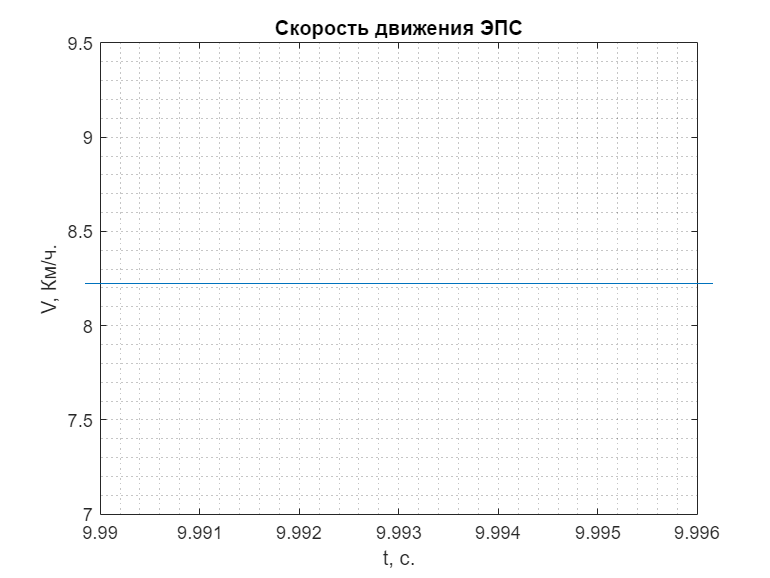

    plot(ans.ScopeTED{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('V, Км/ч.');
    title('Скорость движения ЭПС');
    xlim([x.min x.max]);

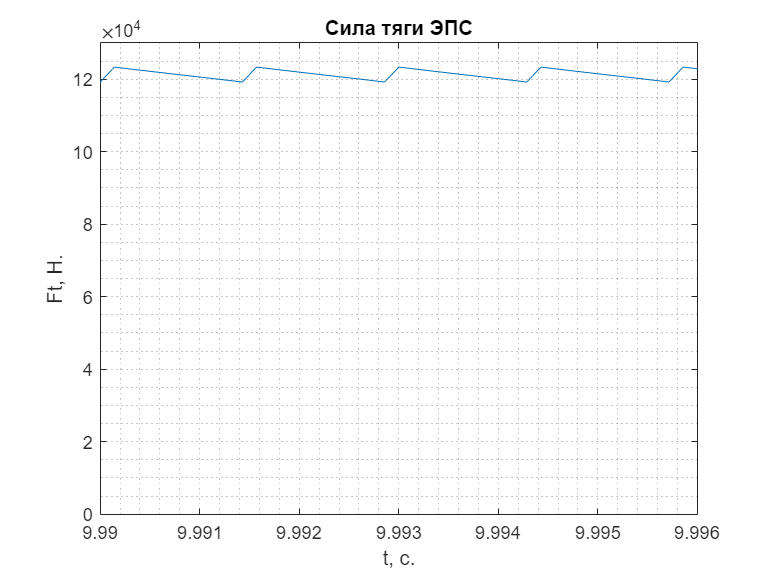

    plot(ans.ScopeTED{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ft, Н.');
    title('Сила тяги ЭПС');
    xlim([x.min x.max]);
        ylim([0 1.3*10^5]);

### **4.2. Диаграммы осциллографа при λ1=0.50, λ2=0.71, β =1, v=42 км/ч  Iуст=250А, Iв=350А:**

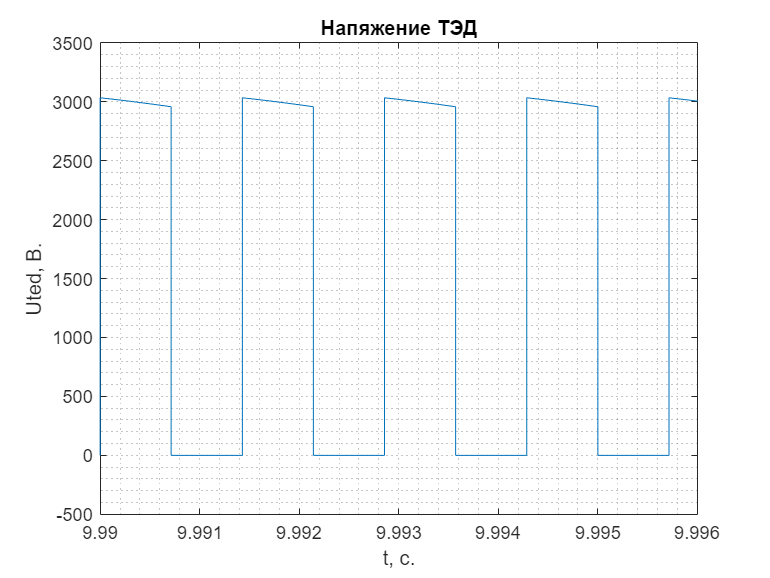

for l1 = 0.5
    OP.lamda1 = l1;
    OP.Veps = V_eps(2:2).';
    OP.lamda2 = lamda2(2:2).';
    sim ('SustemTagSnab_and_TagElPrivod_Scope.slx');
end  
    plot(ans.ScopeTED{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Uted, В.');
    title('Напяжение ТЭД');
    xlim([x.min x.max]);

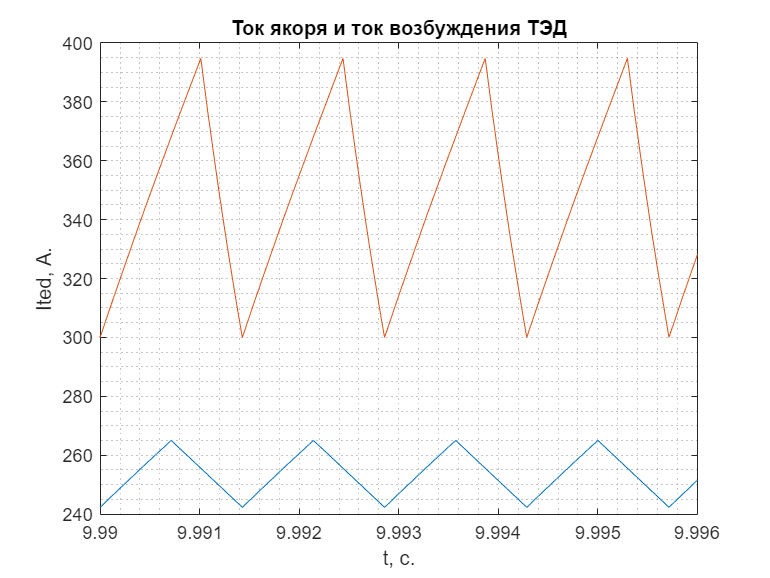

    plot(ans.ScopeTED{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ited, А.');
    title('Ток якоря и ток возбуждения ТЭД');
    xlim([x.min x.max]);

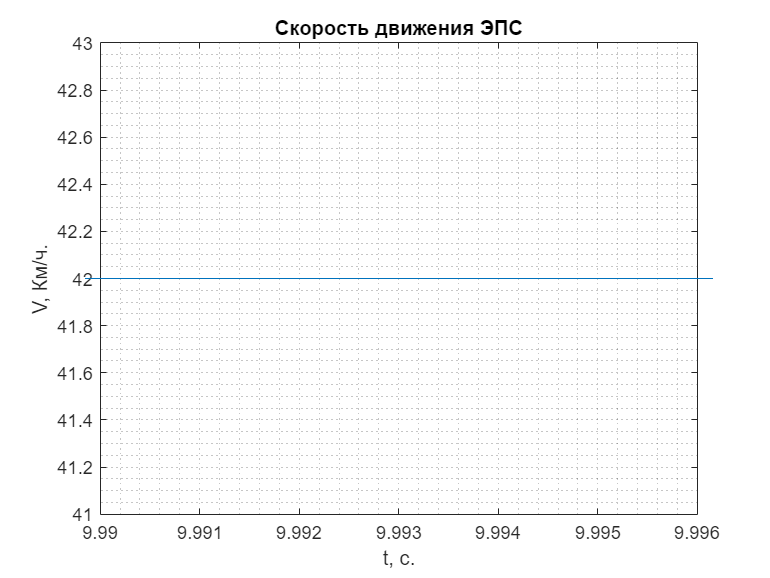

    plot(ans.ScopeTED{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('V, Км/ч.');
    title('Скорость движения ЭПС');
    xlim([x.min x.max]);

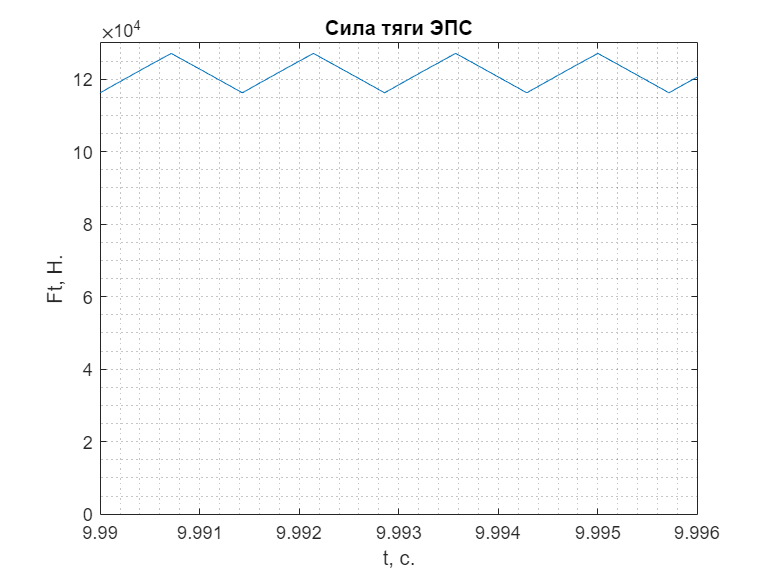

    plot(ans.ScopeTED{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ft, Н.');
    title('Сила тяги ЭПС');
    xlim([x.min x.max]);
        ylim([0 1.3*10^5]);

### **Диаграммы токов и напряжений входного Г-образного фильтра при λ1=0.50, λ2=0.71, β =1, v=42 км/ч  Iуст=250А, Iв=350А:**

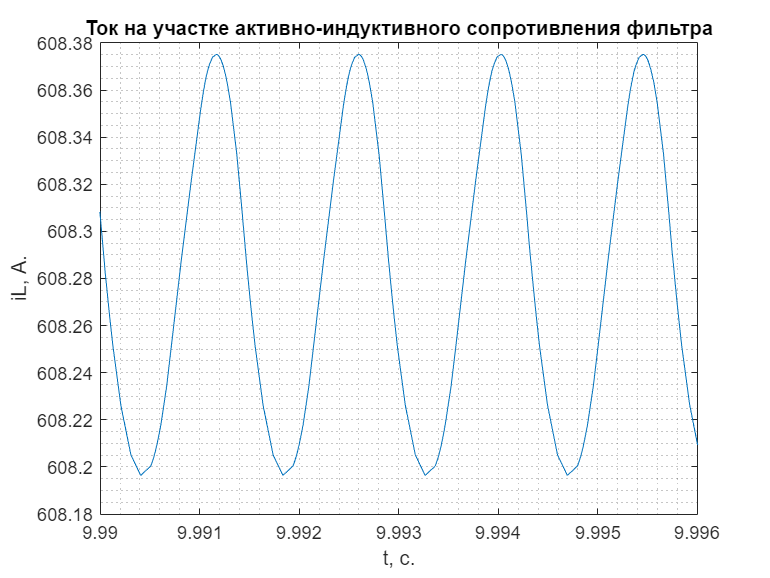

  plot(ans.ScopeFilter{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('iL, А.');
    title('Ток на участке активно-индуктивного сопротивления фильтра');
    xlim([x.min x.max]);

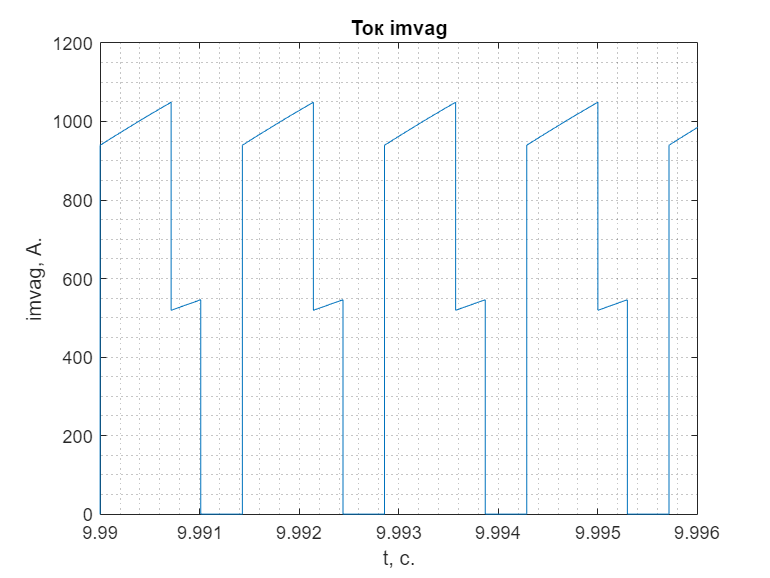

    plot(ans.ScopeFilter{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('imvag, А.');
    title('Ток imvag');
    xlim([x.min x.max]);

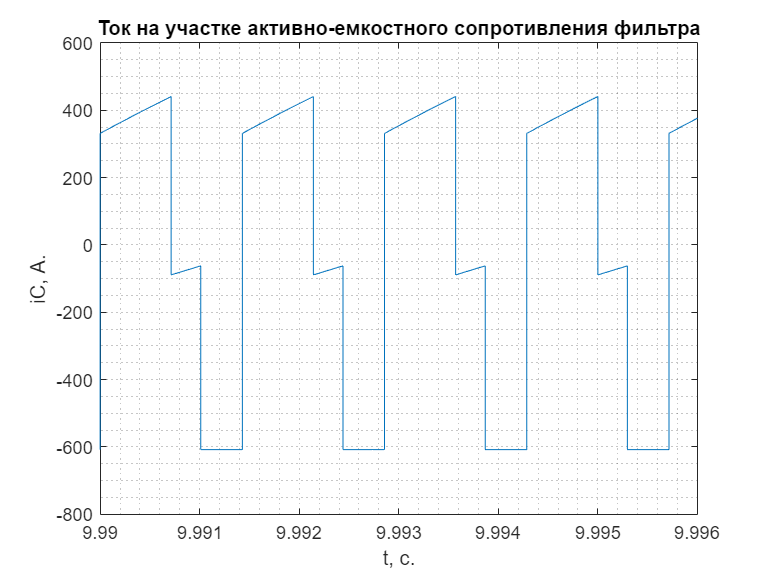

    plot(ans.ScopeFilter{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('iC, А.');
    title('Ток на участке активно-емкостного сопротивления фильтра');
    xlim([x.min x.max]);

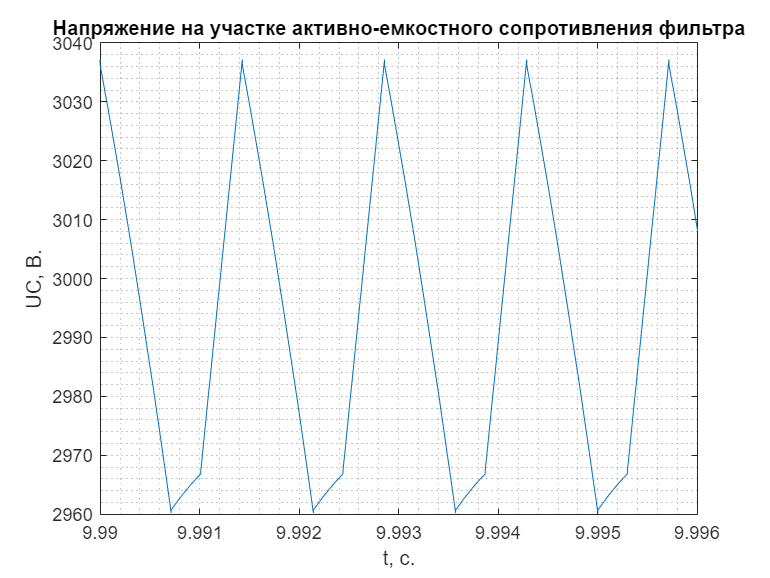

    plot(ans.ScopeFilter{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('UC, В.');
    title('Напряжение на участке активно-емкостного сопротивления фильтра');
    xlim([x.min x.max]);

### **4.3. Диаграммы осциллографа при λ1=0.99, λ2=0.72, β =1, v=78,32 км/ч Iуст=250А, Iв=350А:**

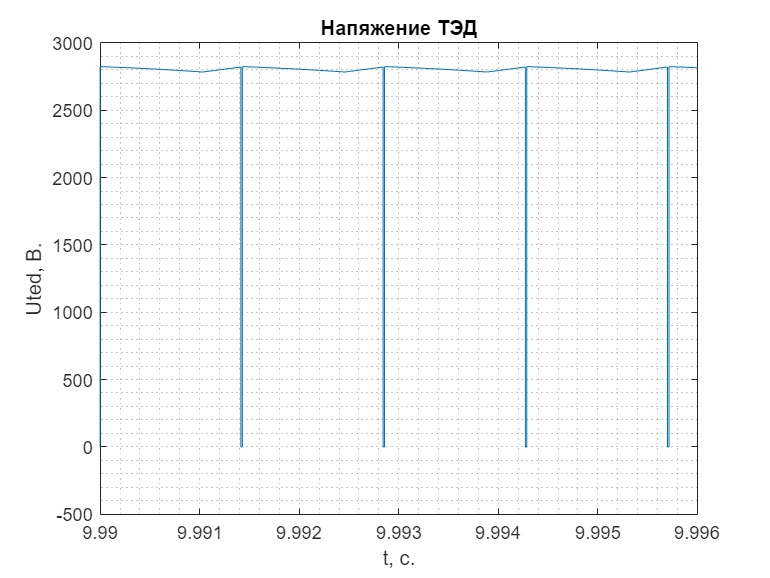

for l1 = 0.99
    OP.lamda1 = l1;
    OP.Veps = V_eps(3:3).';
    OP.lamda2 = lamda2(3:3).';
sim ('SustemTagSnab_and_TagElPrivod_Scope.slx');
end  
    plot(ans.ScopeTED{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Uted, В.');
    title('Напяжение ТЭД');
    xlim([x.min x.max]);

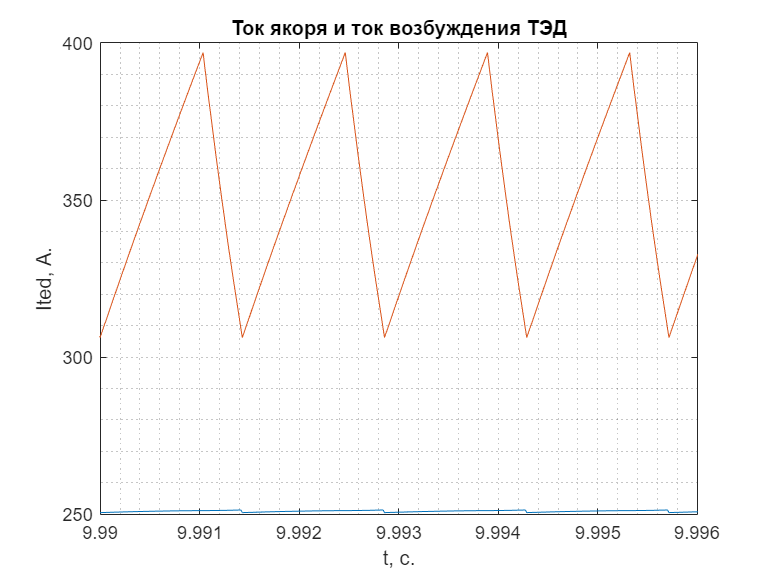

    plot(ans.ScopeTED{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ited, А.');
    title('Ток якоря и ток возбуждения ТЭД');
    xlim([x.min x.max]);

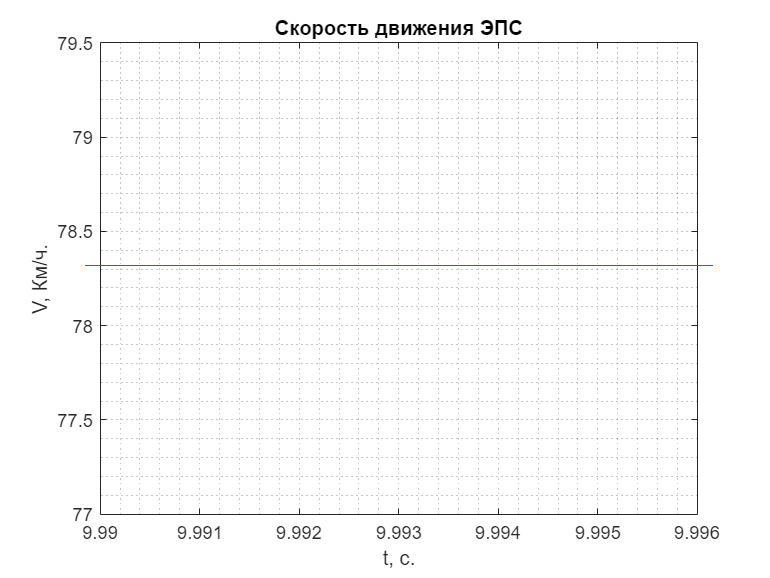

    plot(ans.ScopeTED{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('V, Км/ч.');
    title('Скорость движения ЭПС');
    xlim([x.min x.max]);

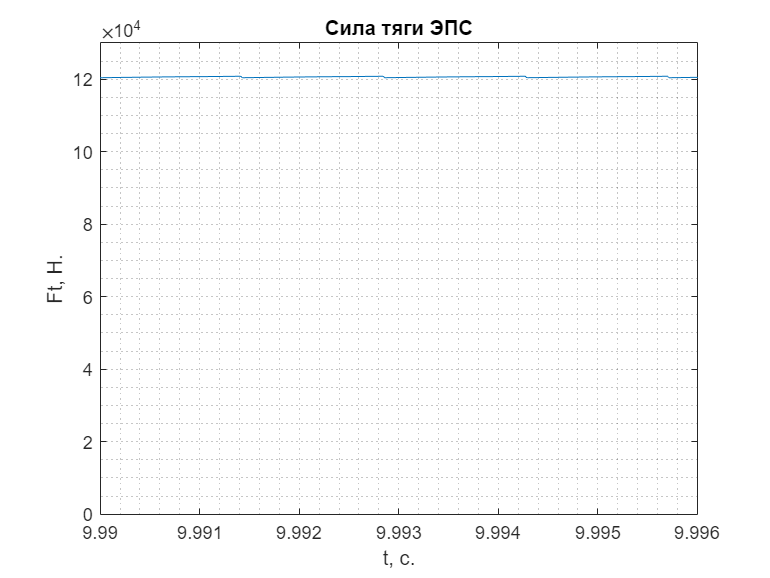

    plot(ans.ScopeTED{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ft, Н.');
    title('Сила тяги ЭПС');
    xlim([x.min x.max]);
        ylim([0 1.3*10^5]);

### **4.4. Диаграммы осциллографа при λ1=0.99, λ2=0.642, β =0,75, v=85,17 км/ч Iуст=250 А, Iв=350*0,75 А:**

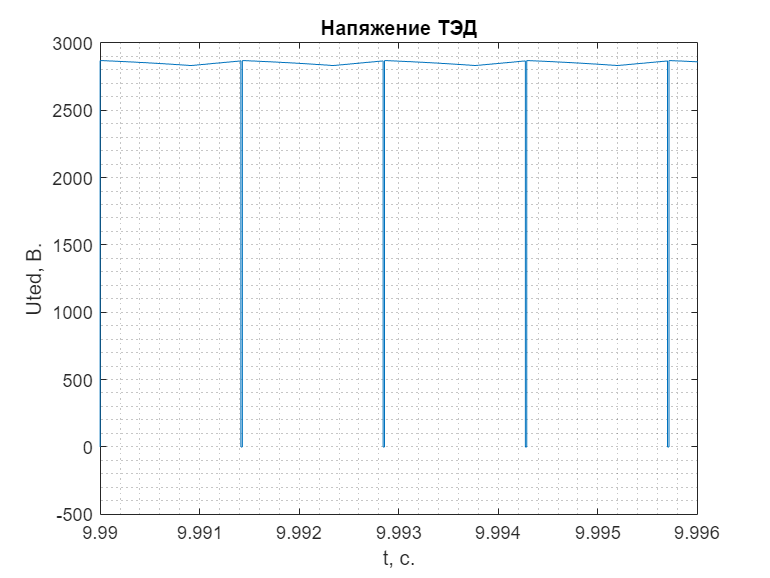

for l1 = 0.99
    OP.lamda1 = l1;
    OP.Veps = V_eps(4:4).';
    OP.lamda2 = lamda2(4:4).'; 
sim ('SustemTagSnab_and_TagElPrivod_Scope.slx');
end  
    plot(ans.ScopeTED{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Uted, В.');
    title('Напяжение ТЭД');
    xlim([x.min x.max]);

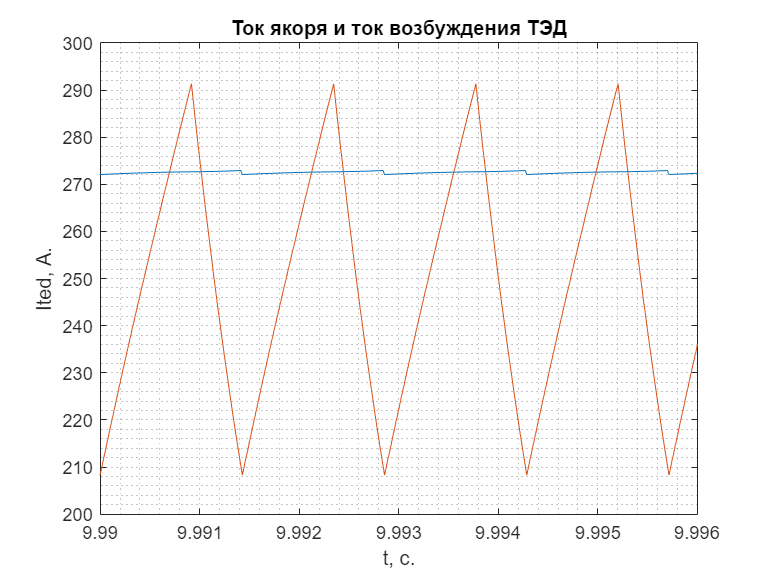

    plot(ans.ScopeTED{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ited, А.');
    title('Ток якоря и ток возбуждения ТЭД');
    xlim([x.min x.max]);

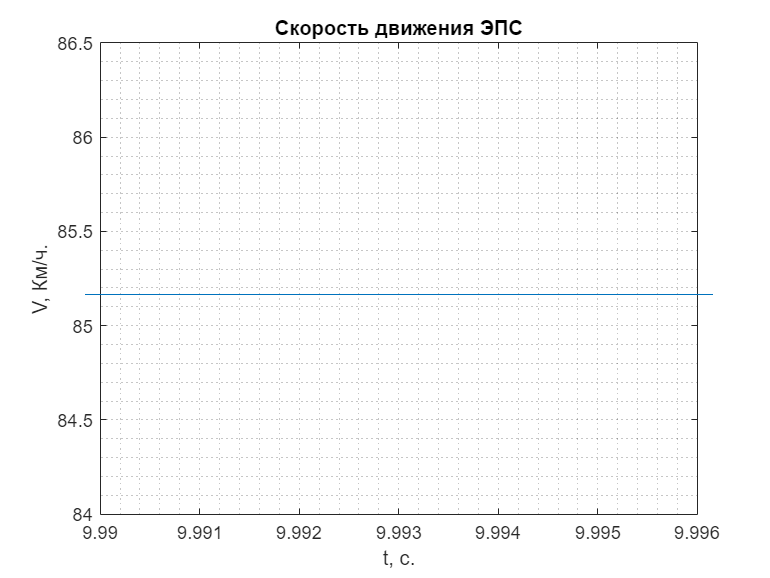

    plot(ans.ScopeTED{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('V, Км/ч.');
    title('Скорость движения ЭПС');
    xlim([x.min x.max]);

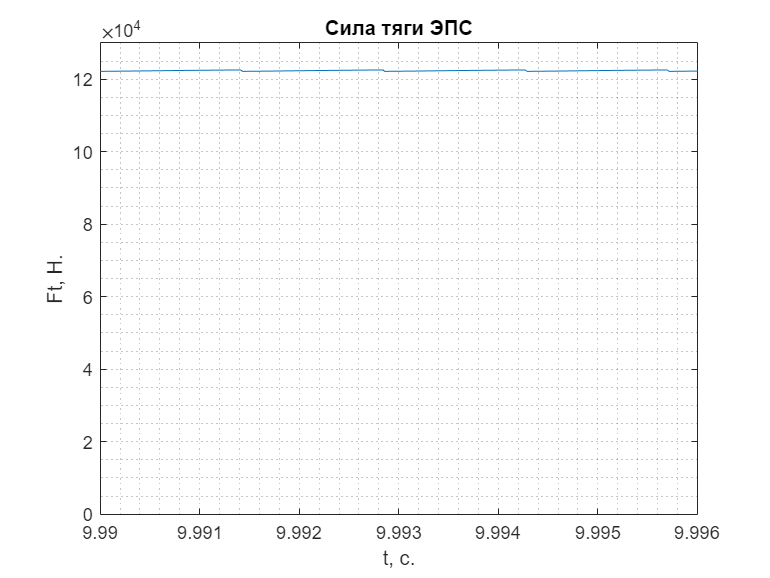

    plot(ans.ScopeTED{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ft, Н.');
    title('Сила тяги ЭПС');
    xlim([x.min x.max]);
        ylim([0 1.3*10^5]);

### **4.5. Диаграммы осциллографа при λ1=0.99, λ2=0.548, β =0,5, v=96,38 км/ч Iуст=250 А, Iв=350*0,5 А:**

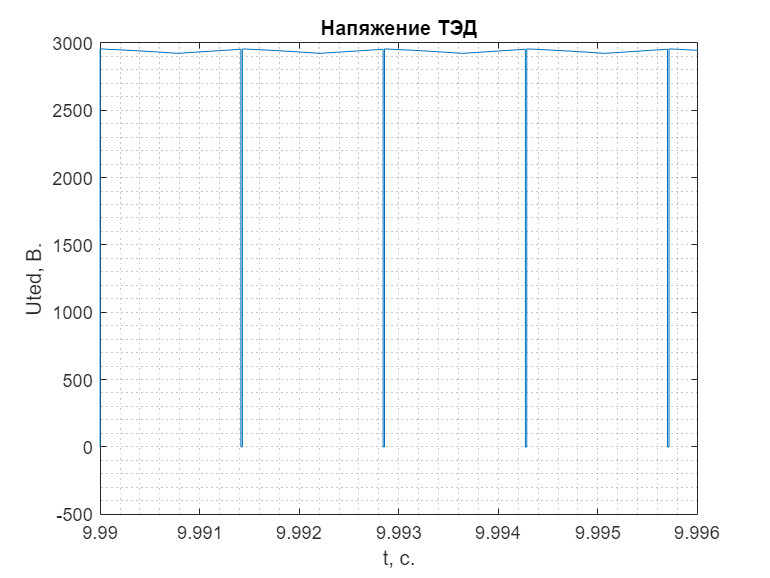

for l1 = 0.99
    OP.lamda1 = l1;
    OP.Veps = V_eps(5:5).';
    OP.lamda2 = lamda2(5:5).'; 
sim ('SustemTagSnab_and_TagElPrivod_Scope.slx');
end  
    plot(ans.ScopeTED{1}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Uted, В.');
    title('Напяжение ТЭД');
    xlim([x.min x.max]);

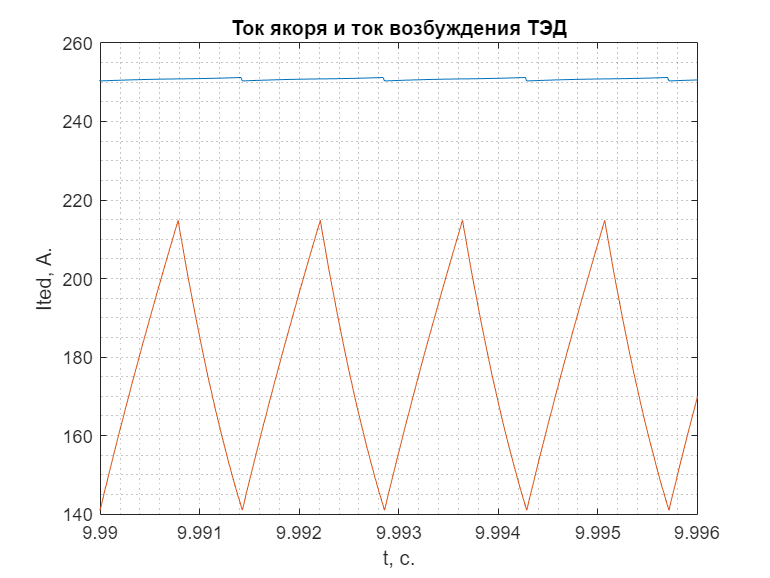

    plot(ans.ScopeTED{2}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ited, А.');
    title('Ток якоря и ток возбуждения ТЭД');
    xlim([x.min x.max]);

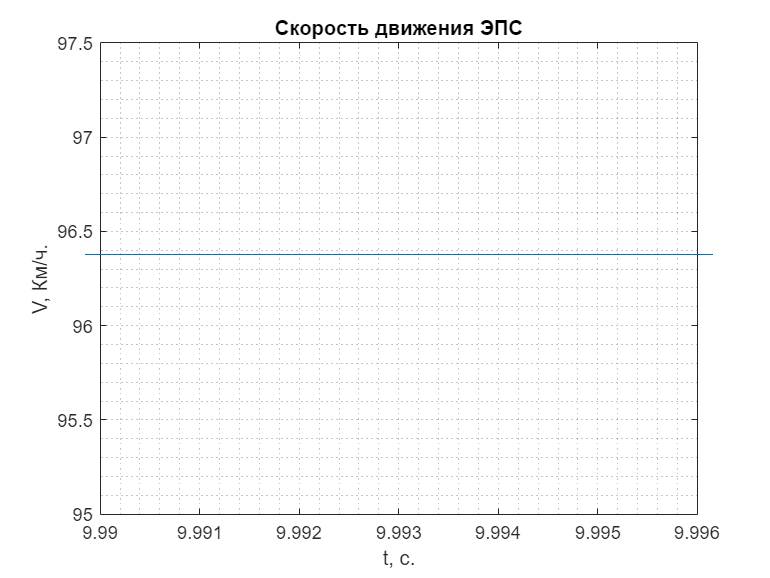

    plot(ans.ScopeTED{3}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('V, Км/ч.');
    title('Скорость движения ЭПС');
    xlim([x.min x.max]);

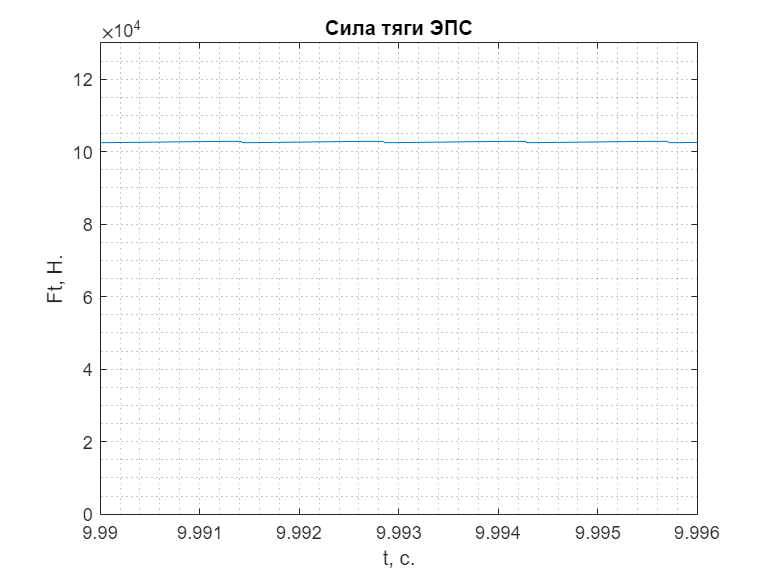

    plot(ans.ScopeTED{4}.Values);
    grid("minor")
    xlabel('t, с.');
    ylabel('Ft, Н.');
    title('Сила тяги ЭПС');
    xlim([x.min x.max]);
    ylim([0 1.3*10^5]);

## **Заключение**

В ходе выполнения типового задания №3 была произведена разработка математической модели разомкнутой системы  управления электроприводом. Построены компьютерные модели системы тягового электроснабжения и системы тягового электропривода, а также произведен расчет и ввод параметров системы. В ходе выполнения исследования были получены зависимости коэффициента заполнения λ2 и скорости ЭПС v от заданного коэффициента заполения λ1 и токов в цепи якоря и обмотки возбуждения. На основании проведенного исследования получены диаграммы напряжения на нагрузке, токов ТЭД, скорости и силы тяги ЭПС, а также диаграммы токов и напряжений на входном Г-образном фильтре (в случае λ1=0,5 , ОП=100%).

Полученные диаграммы в разработанной модели являются адекватными характеристиками , сделавательно модель является работоспособной.